# Battery Electric Vehicle System - Main Script

## Introduction

This is a simple, fast running BEV model which can estimate the electrical efficiency of the vehicle. It is also suitable for further customizations for more focused analysis of individual components at vehicle system level.

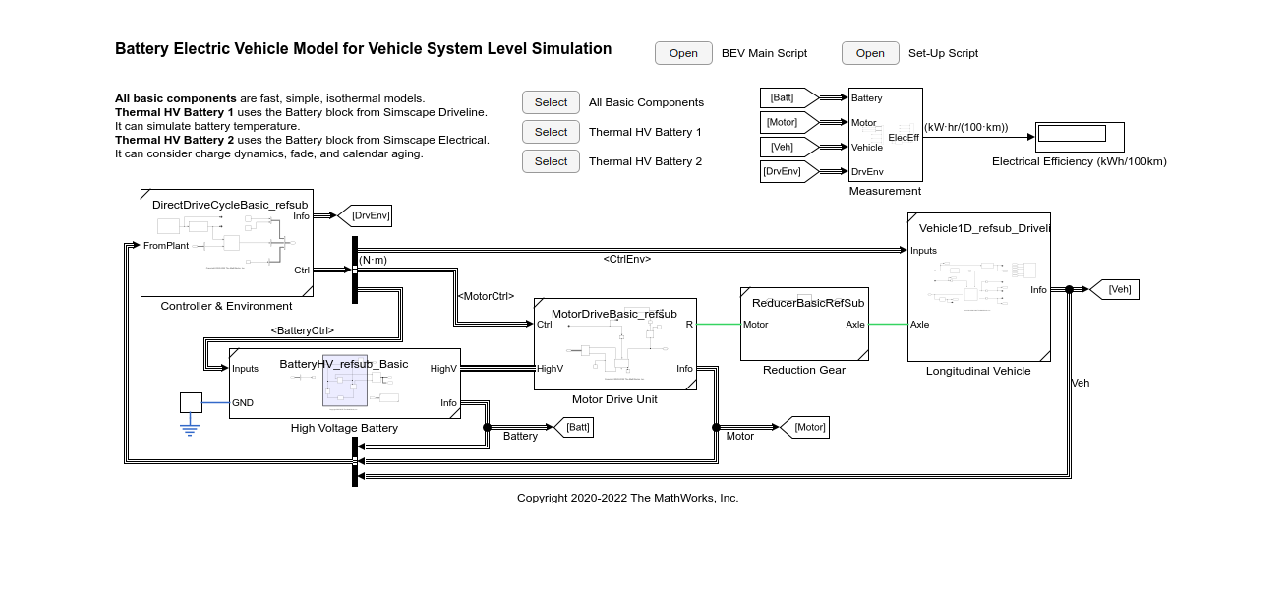

% Load the model and do basic set-up.
modelName = "BEV_system_model";
load_system(modelName)
BEV_params
BEV_resetReferencedSubsystems

% Update model for screenshot.
set_param(modelName, SimulationCommand = "update")

% Take screenshot, save, and show it.
imgFolder = fullfile(currentProject().RootFolder, "BEV", "images");
result = screenshotSimulink( ...
            SimulinkModelName = modelName, ...
            SaveFolder = imgFolder );
imshow(result.OutputFullPath)

## Open System Model

Click the button below to open the BEV system model.

 
open_system("BEV_system_model")

Click the button below to open the script defining the model parameters.

 
edit("BEV_params")

## Run Simulation

Set up simulation conditions and run simulation. To run this script from this section to the end, click the Run to End button in the toolstrip. Make sure that the `modelName` variable, loaded at the top of this script, exists in the base workspace.

% Drive cycle.
% This is used later in this script to configure the Drive Cycle Source block in
% the Controller & Environment subsystem of the BEV system model.
driveCycle = "FTP75";

% Simulation end time in seconds.
% This must be consistent with the drive cycle specified just above.
t_end = seconds(2474);

% Folder to store simulation results, relative to the project root folder.
prjRoot = currentProject().RootFolder;
simResultFileFolder = fullfile(prjRoot, "BEV", "results");

% File name to save simulation results.
% CSV format is used to save the data.
simResultFileName  = "BEV_SimulationResult_1.csv";

% Signal names to save in file.
% These must be specified in the model as signal logging names.
dataColumns = [ ...
  "HV Battery SOC", "HV Battery Power", "HV Battery Current", ...
  "Vehicle G Force", "Vehicle Speed" ];

% Basic set-up of the model for simulation.
load_system(modelName)
BEV_params
BEV_resetReferencedSubsystems

% Override model parameters if you want.
% This must come after the above basic set-up.
% Below is just an example:
batteryHV.nominalVoltage_V = 350;
batteryHV.nominalCapacity_kWh = 4;
batteryHV.voltagePerCell_V = 3.7;  % Open Circuit Voltage. 3.5V to 3.7V assuming Lithium-ion
batteryHV.nominalCharge_Ahr = ...
  batteryHV.nominalCapacity_kWh / batteryHV.nominalVoltage_V * 1000;
% Initial conditions
initial.hvBattery_SOC_pct = 70;
initial.hvBattery_Charge_Ahr = ...
  batteryHV.nominalCharge_Ahr * initial.hvBattery_SOC_pct/100;

% Create a simulation input object to configure the model and simulation.
simIn = Simulink.SimulationInput(modelName);

% Set simulation end time.
t_end_s = seconds(t_end);
simIn = setModelParameter(simIn, StopTime=num2str(t_end_s));

% Set drive cycle in the Drive Cycle Source block.
simIn = setBlockParameter( simIn, ...
  modelName + "/Controller & Environment/Drive Cycle Source", ...
  cycleVar = driveCycle );

% Start simulation.
simOut = sim(simIn);

## Plot Result

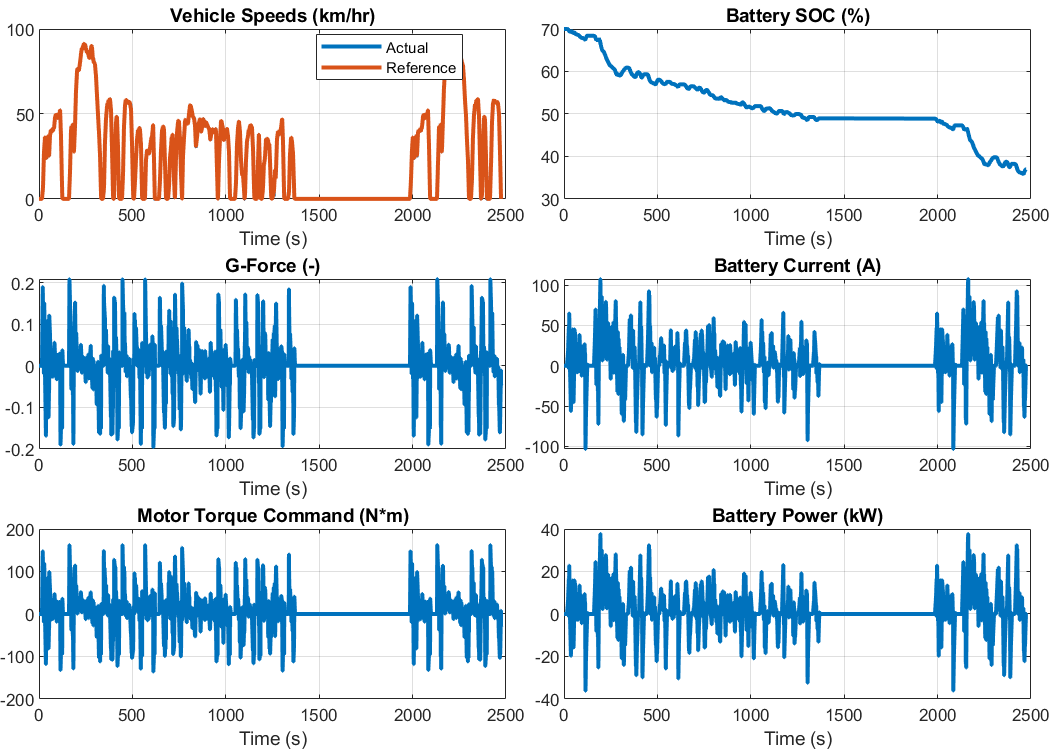

fig = BEV_plotResults(simOut.logsout);
exportgraphics(fig, fullfile(imgFolder, "image_BEV_sim_result_plots.png"))

## Save Result

Save logged signals to CSV file for later analysis. Text format is used rather than binary format for saving the data. Text format works better when the data size is small and the file is version-managed with a source control tool such as git.

% Extract logged signals at once with extractTimetable.
resultTable = extractTimetable(simOut.logsout);

% Adjust time format so as not to lose the subsecond information.
resultTable.Time.Format = 'hh:mm:ss.SSSS';

% Select the logged signals to save.
resultTable = resultTable(:, dataColumns);

% Add unit information to signal names.
varNames = string(resultTable.Properties.VariableNames');
% disp(varNames)
varUnits = string(resultTable.Properties.VariableUnits');
% disp(varUnits)
varNames2 = varNames + " (" + varUnits + ")";
disp(varNames2)

    "HV Battery SOC (%)"
    "HV Battery Power (kW)"
    "HV Battery Current (A)"
    "Vehicle G Force (1)"
    "Vehicle Speed (km/hr)"



resultTable.Properties.VariableNames = varNames2;

% Save.
simResultFile_FullPath = fullfile(simResultFileFolder, simResultFileName);
writetimetable(resultTable, simResultFile_FullPath)

## Analyse Result

To make the workflow complete, this section reads the simulation result which was saved in the previous section, and do some analysis on the data. (If the path to the simulation result file is specified, the code in this section should work independently without previous sections.)

% Read a CSV file containing simulation result and store it to a timetable.
% If the simResultFile_FullPath variable right below is explicitly specified,
% the code in this section should independently work.
data = readtimetable(simResultFile_FullPath, VariableNamingRule="preserve");

% Adjust time format.
data.Time.Format = 's';

% Separate variable names and unit strings.
varNames_with_unit = data.Properties.VariableNames';
% disp(varNames_with_unit)
varNames = extractBefore(varNames_with_unit, " (");
disp(varNames)

    {'HV Battery SOC'    }
    {'HV Battery Power'  }
    {'HV Battery Current'}
    {'Vehicle G Force'   }
    {'Vehicle Speed'     }



varUnits = extractBetween(varNames_with_unit, "(", ")");
disp(varUnits)

    {'%'    }
    {'kW'   }
    {'A'    }
    {'1'    }
    {'km/hr'}



data.Properties.VariableNames = varNames;
data.Properties.VariableUnits = varUnits;

% Define a little utility to manipulate the unit representation
% in Simscape's physical values.
tidyUnit = @(x,u) simscape.Value( value(x,u), u );

Time

t = simscape.Value( seconds(data.Time), 's' );
dt = diff(t);

Travelled Distance

dataVehSpd = data.("Vehicle Speed");
unitStr = varUnits(varNames == "Vehicle Speed");
vehicleSpeed = simscape.Value(dataVehSpd, unitStr{:});
averageSpeed = sum(vehicleSpeed)/numel(vehicleSpeed)

averageSpeed =    35.7143 : km/hr


maxSpeed = max(vehicleSpeed)

maxSpeed =    91.2571 : km/hr


tmpDistance = sum(vehicleSpeed(2:end).*dt);
travelledDistance = tidyUnit( tmpDistance, 'km' )

travelledDistance =    17.7686 : km


G Force

G = data.("Vehicle G Force");
min(G), max(G)

ans = -0.1958

ans = 0.2085

Battery Power

dataBattPwr = data.("HV Battery Power");
unitStr = varUnits(varNames == "HV Battery Power");
batteryPower = simscape.Value(dataBattPwr, unitStr{:});  % J/s
batteryEnergyUsed = sum(batteryPower(2:end).*dt)

batteryEnergyUsed =    4.7948e+03 : kW*s


batteryEnergyUsed = tidyUnit(batteryEnergyUsed, 'kW*hr')

batteryEnergyUsed =     1.3319 : hr*kW


energyEfficiency_kWh_per_100km = 100 * value(batteryEnergyUsed / travelledDistance, 'kW*hr/km')

energyEfficiency_kWh_per_100km = 7.4957

*Copyright 2022 The MathWorks, Inc.*